clear 

x.data = [0,-1,1,0];
x.offset = -1

x = struct with fields:
      data: [0 -1 1 0]
    offset: -1



h.data = [0,1,1,-1,-1,0];
h.offset = -2

h = struct with fields:
      data: [0 1 1 -1 -1 0]
    offset: -2


h_flip = flipit(h)

h_flip = struct with fields:
      data: [0 -1 -1 1 1 0]
    offset: -3


y.data = zeros(1,length(x.data)+length(h.data)-1)

y = struct with fields:
    data: [0 0 0 0 0 0 0 0 0]


y.offset = 0

y = struct with fields:
      data: [0 0 0 0 0 0 0 0 0]
    offset: 0


disp('Begin for loop')

Begin for loop


    "n="    "1"



y_temp = struct with fields:
      data: [0 0 0 0]
    offset: -1


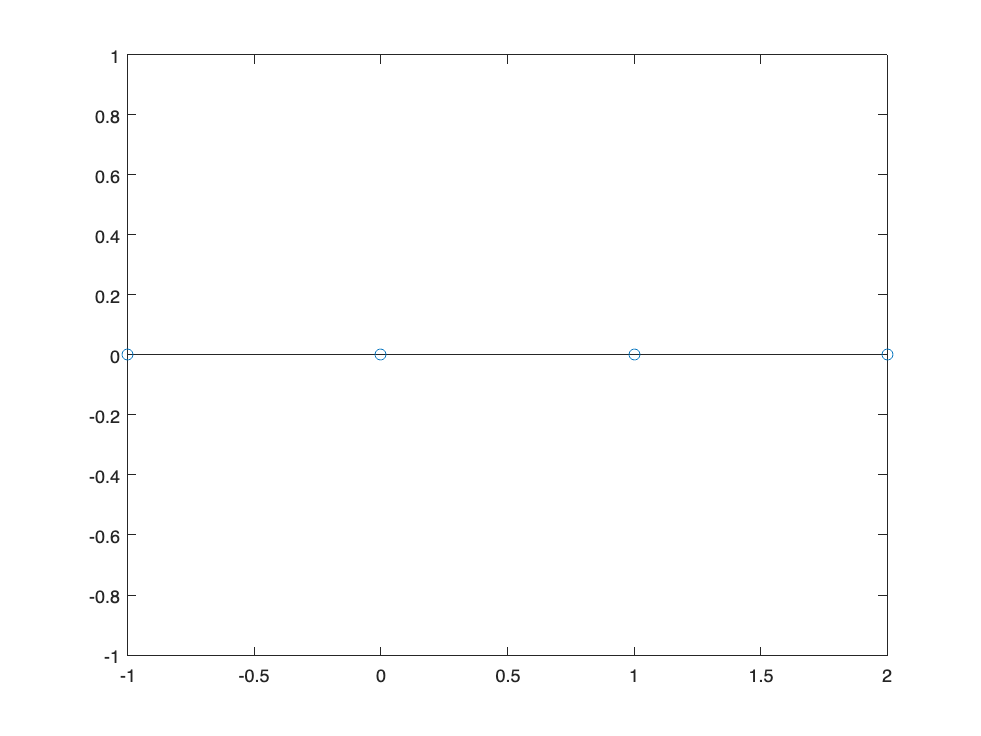

    "n="    "2"



y_temp = struct with fields:
      data: [0 -1 1 0]
    offset: 0


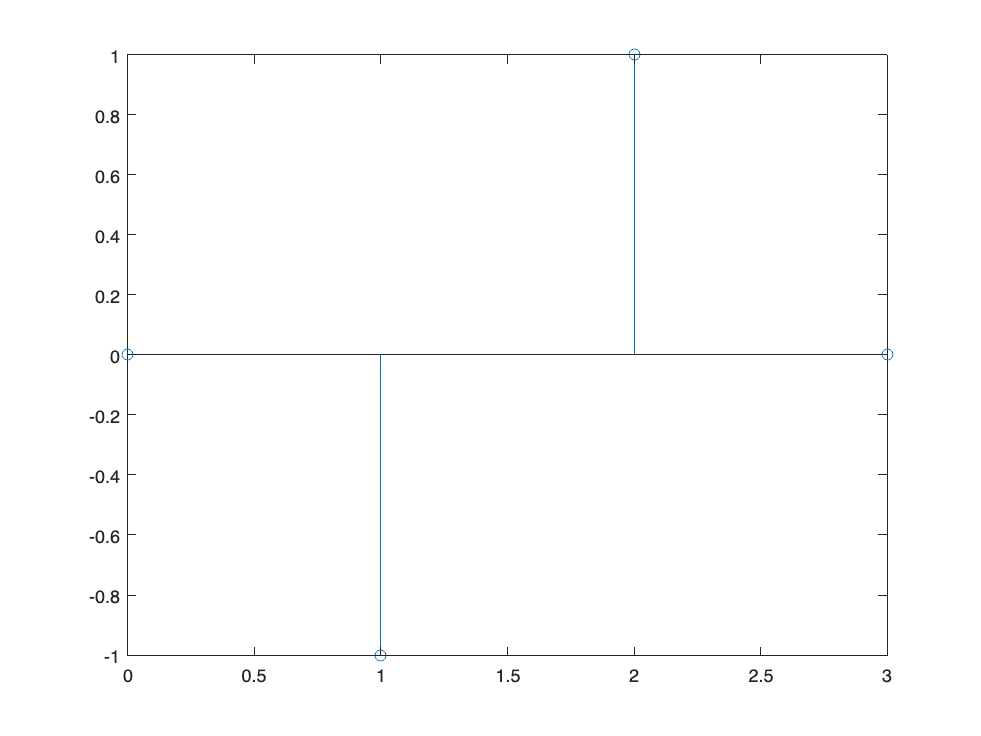

    "n="    "3"



y_temp = struct with fields:
      data: [0 -1 1 0]
    offset: 1


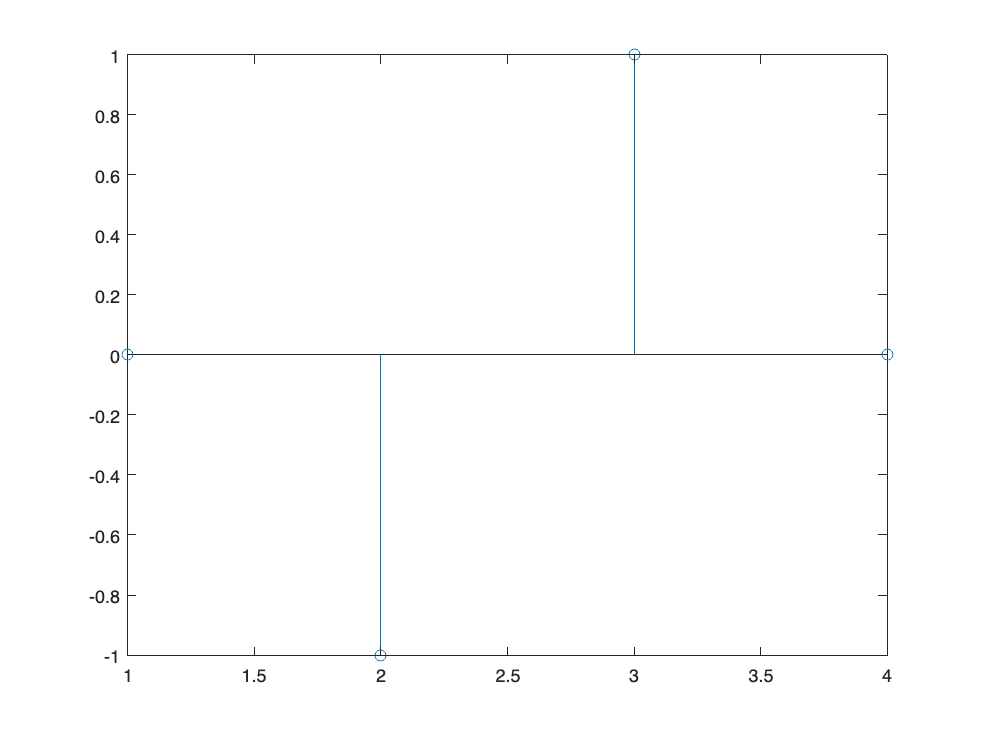

    "n="    "4"



y_temp = struct with fields:
      data: [0 1 -1 0]
    offset: 2


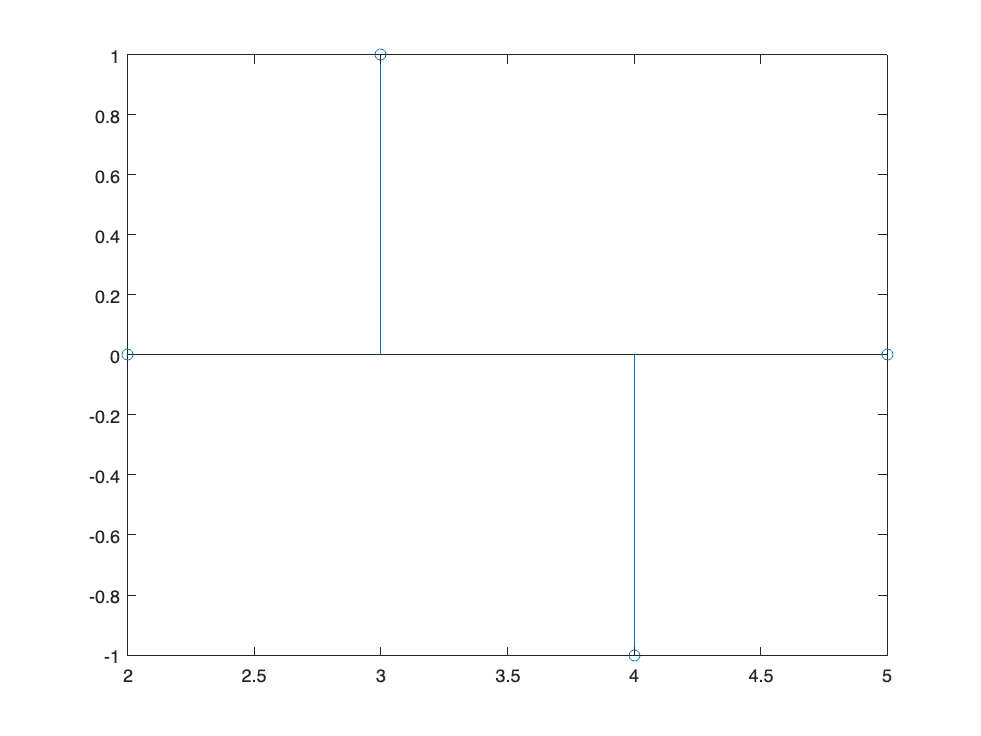

    "n="    "5"



y_temp = struct with fields:
      data: [0 1 -1 0]
    offset: 3


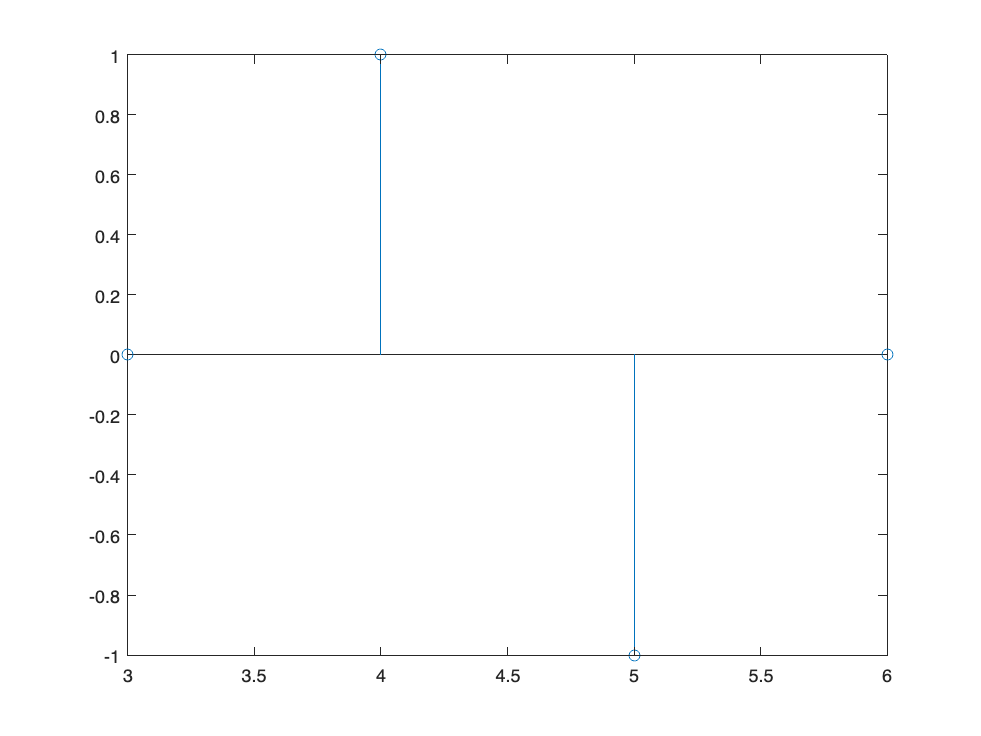

    "n="    "6"



y_temp = struct with fields:
      data: [0 0 0 0]
    offset: 4


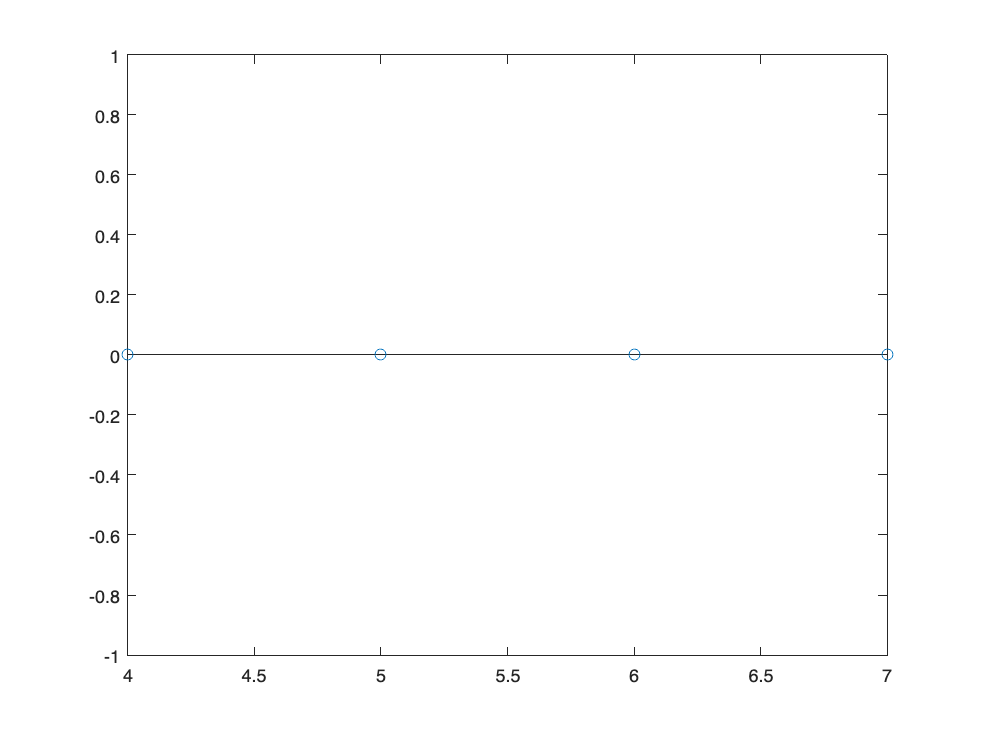


for n=1:length(h.data)

    disp(["n=",n])
    x_shifted = shiftit(x, n-1);
    y_temp = multit(h.data(n),x_shifted)
    figure;
    stemit(y_temp);
    % title('n=',n-1);
    y = addit(y, y_temp);
end

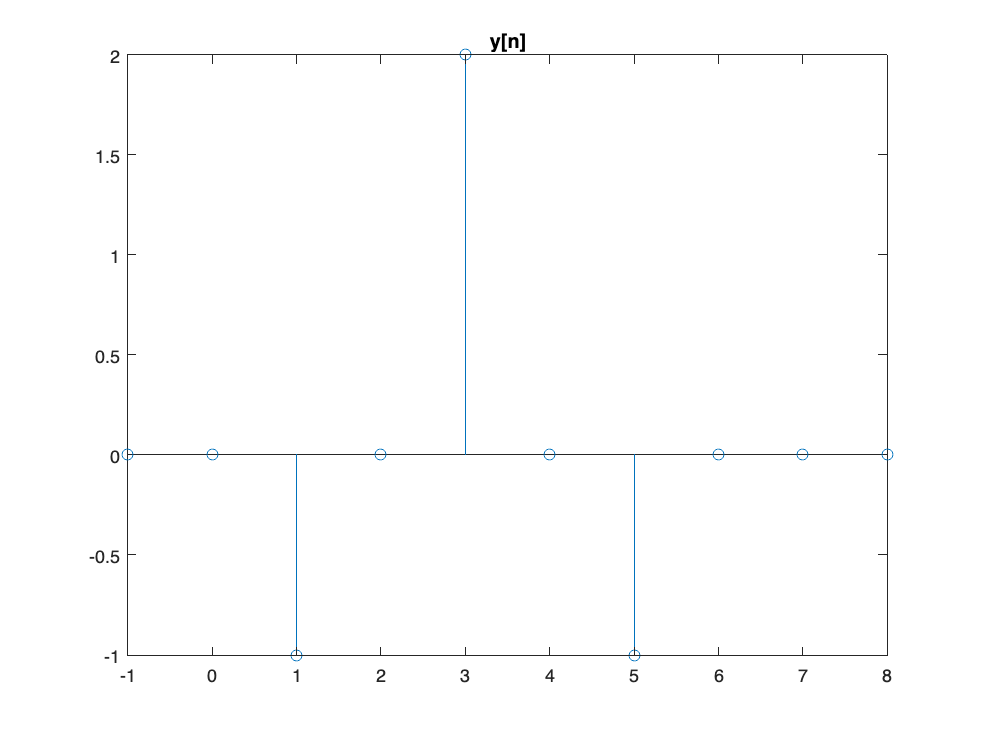

figure;
stemit(y);
title('y[n]');